# Import data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 11-Oct-2021 23:36:12

## Set up the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 2);

% Specify sheet and range
opts.Sheet = "Лист1";
opts.DataRange = "G2:H26";

% Specify column names and types
opts.VariableNames = ["V_2", "A_2"];
opts.VariableTypes = ["double", "double"];

% Import the data
Untitled = readtable("C:\Users\Marina\Documents\Без имени 1.xlsx", opts, "UseExcel", false)

Untitled = 25×2 table
     V_2      A_2  
    _____    ______

    24.95    121.74
     21.9    124.28
    22.09    124.83
    18.92    123.05
       16    119.17
    13.01    111.54
     9.99     97.98
     8.03      85.3
     6.02      68.7
     3.96      47.7
        4     48.07
     2.01     24.53
     0.53      5.75
      0.5      5.33
        0     -6.15
       -2    -12.12


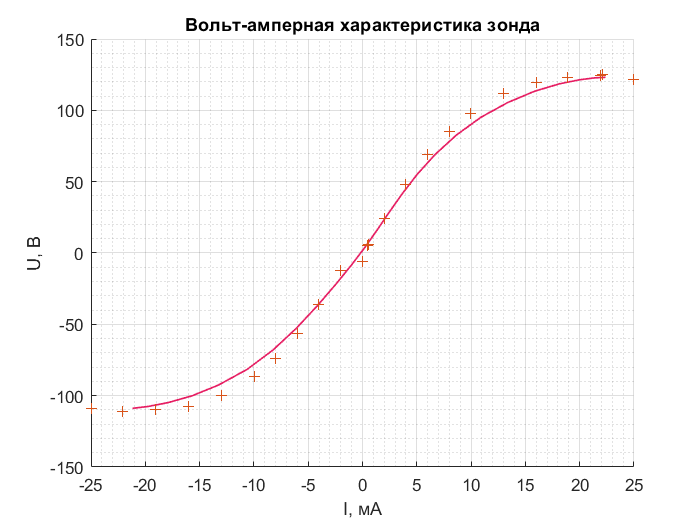

hold on
grid on
grid("minor")
V_2= [
     24.95
      21.9
     22.09
     18.92
        16
     13.01
      9.99
      8.03
      6.02
      3.96
         4
      2.01
      0.53
       0.5
         0
        -2
     -4.03
     -5.98
     -8.05
     -9.96
    -12.99
    -15.99
    -19.06
    -22.07
    -24.97];
A_2 = [     
     121.74
     124.28
     124.83
     123.05
     119.17
     111.54
      97.98
       85.3
       68.7
       47.7
      48.07
      24.53
       5.75
       5.33
      -6.15
     -12.12
     -36.28
     -56.49
      -73.8
     -86.32
     -99.92
    -107.67
    -109.66
    -111.44
    -108.76

];
V_2_S = smoothdata(V_2,'gaussian',10);
A_2_S = smoothdata(A_2,'gaussian',10);
plot(V_2_S,A_2_S,"LineWidth",1,"Color",[0.9 0.108 0.38]);
scatter(V_2, A_2, "Marker","+","MarkerEdgeColor","flat");
title("Вольт-амперная характеристика зонда")
xlabel('I, мА')
ylabel('U, В')

xlim([-25.0 25.0])
ylim([-150 150])

## Clear temporary variables

clear opts